# 1. 三次多项式轨迹

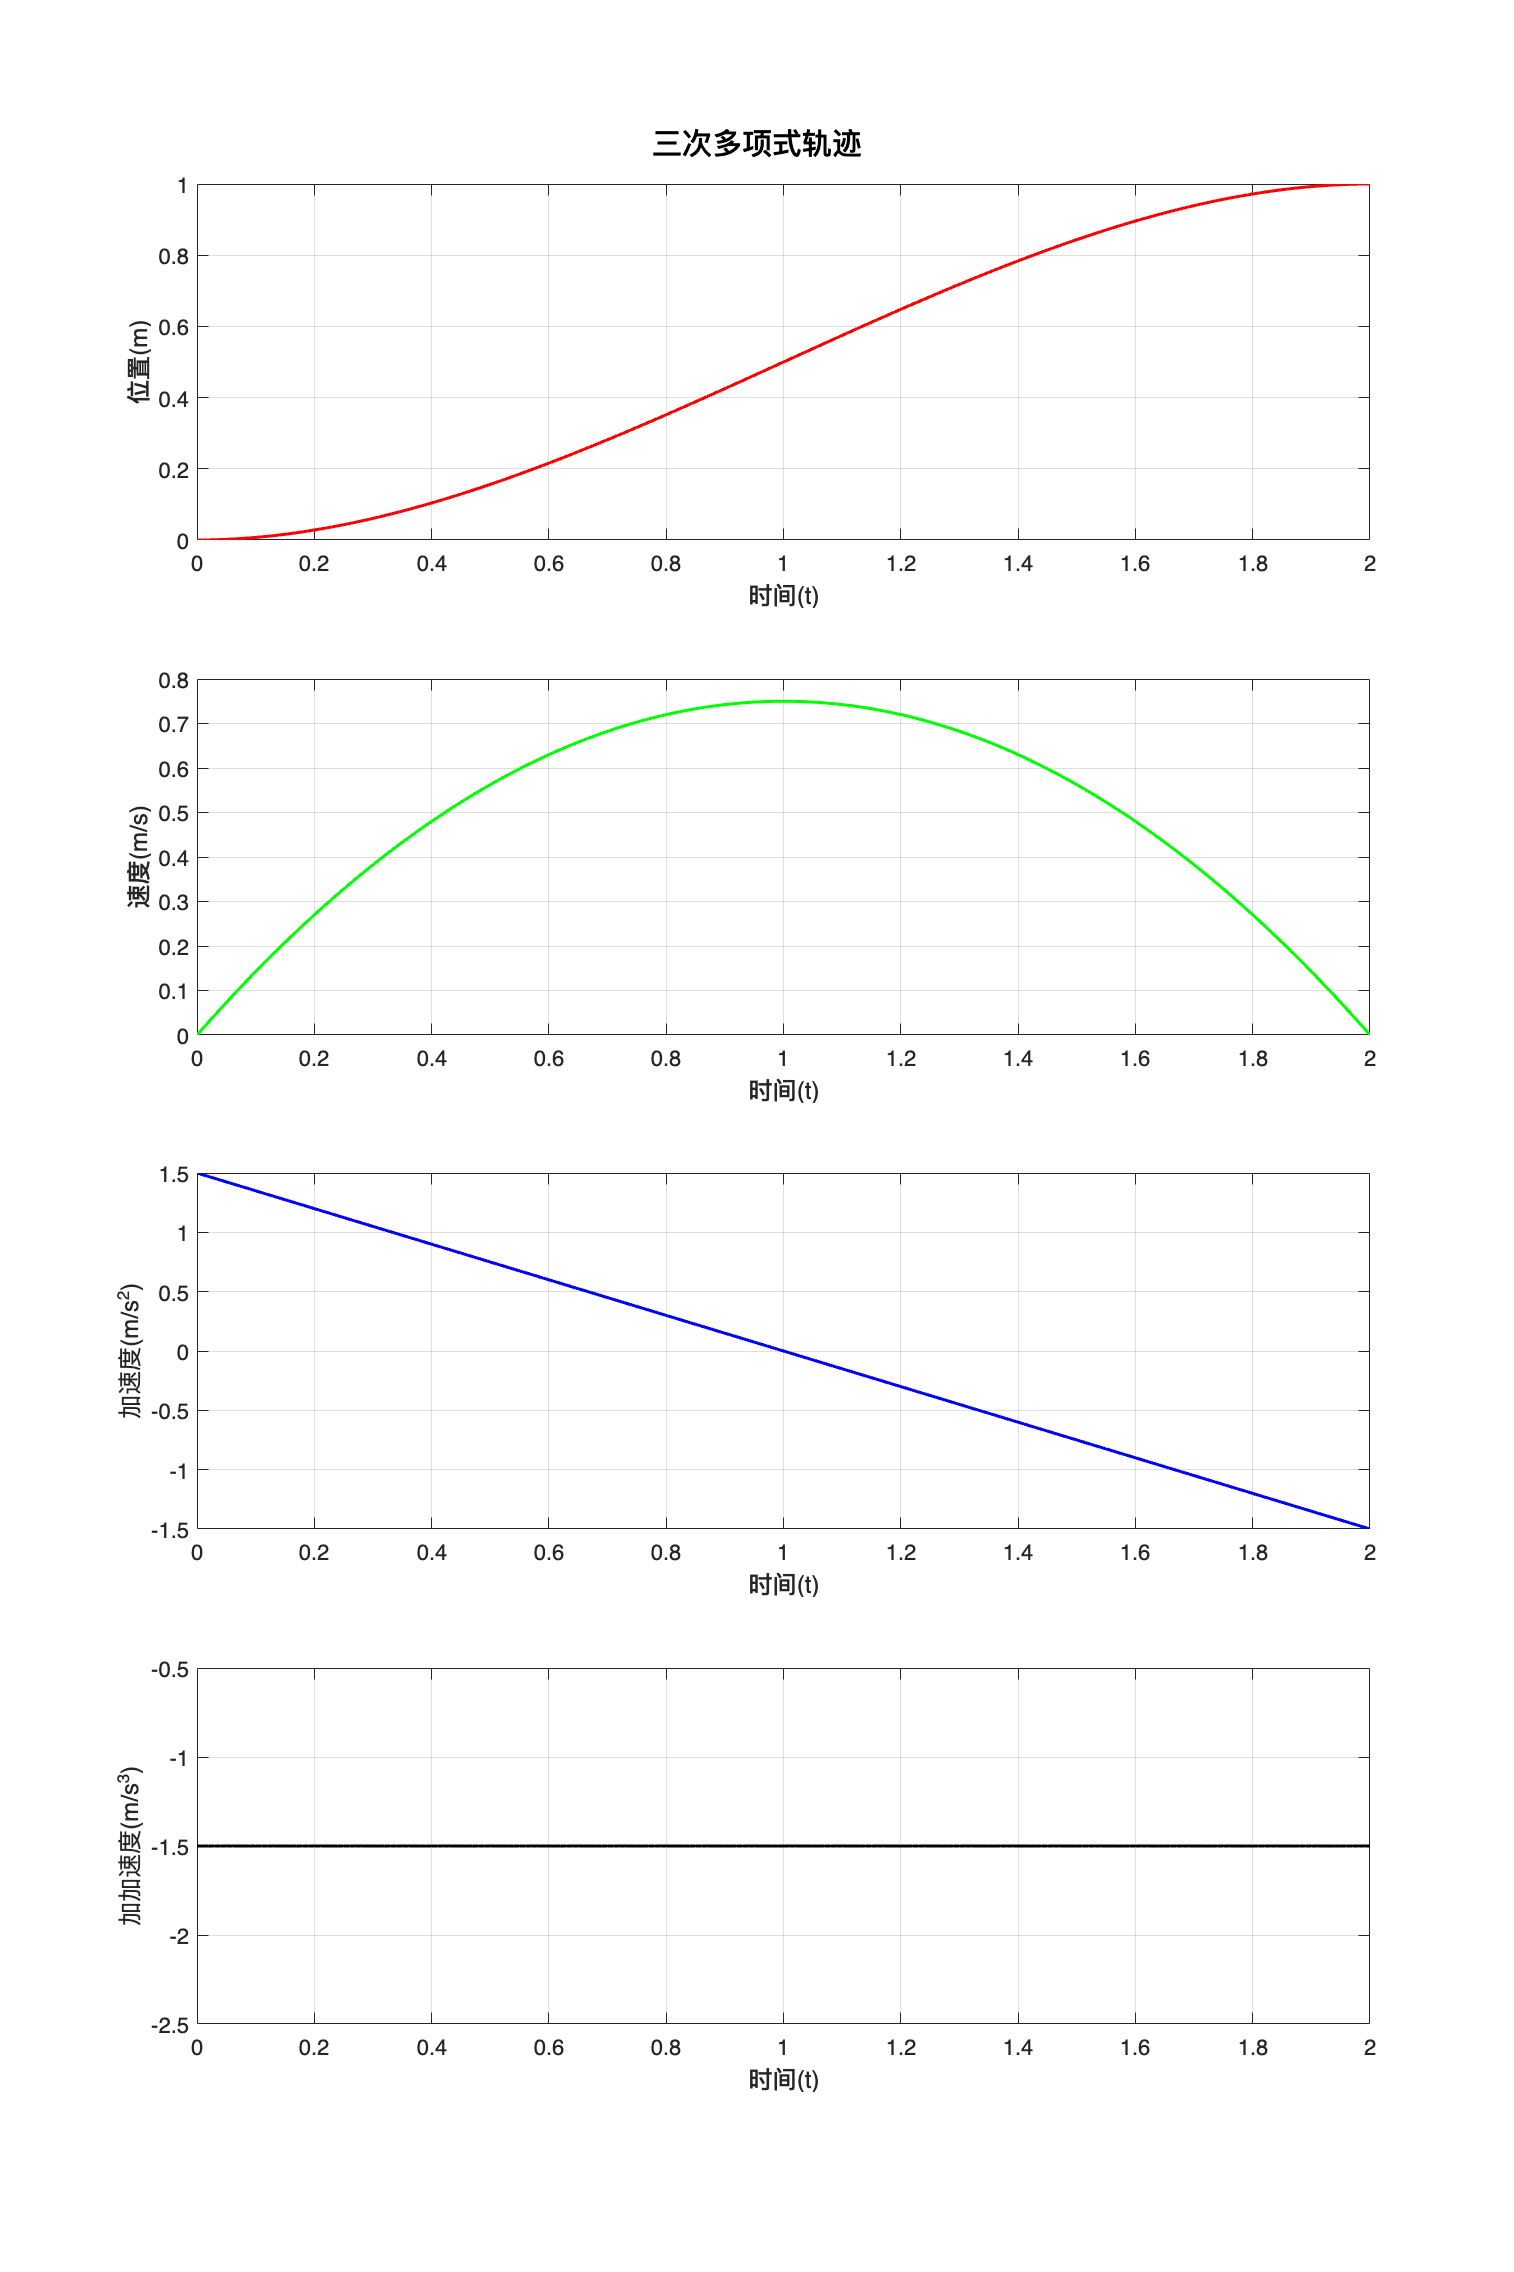

close all;
clear;
clc;

% 设定参数
T = 2;
dT = 0.01;
t0 = 0;  s0 = 0;  v0 = 0;   % 起点
te = T;  se = 1;  ve = 0;   % 终点

% 计算系数
a0 = s0;
a1 = 0;
a2 = (3/te^2)*(se - s0);
a3 = (-2/te^3)*(se - s0);

% 计算曲线
t  = 0: dT: T; 
q  = a0 + a1*t + a2*t.^2 + a3*t.^3;  % 位置
qd = a1 + 2*a2*t + 3*a3*t.^2;        % 速度
qdd = 2*a2 + 6*a3*t;                 % 加速度
qddd = 6*a3*ones(size(t));           % 加加速度

% 绘制曲线
figure('position',[0,0, 1200,1800]);
sgtitle('三次多项式轨迹') 

subplot(4,1,1); plot(t, q, 'r','LineWidth', 1.5);  
xlabel('时间(t)'),ylabel('位置(m)'); grid; 

subplot(4,1,2); plot(t, qd,  'g','LineWidth', 1.5); 
xlabel('时间(t)'),ylabel('速度(m/s)');  grid;

subplot(4,1,3); plot(t, qdd, 'b','LineWidth', 1.5);  
xlabel('时间(t)'),ylabel('加速度(m/s^2)'); grid;

subplot(4,1,4); plot(t, qddd,'k','LineWidth', 1.5);  
xlabel('时间(t)'),ylabel('加加速度(m/s^3)'); grid;

# 2. 五次多项式轨迹（Matlab函数）

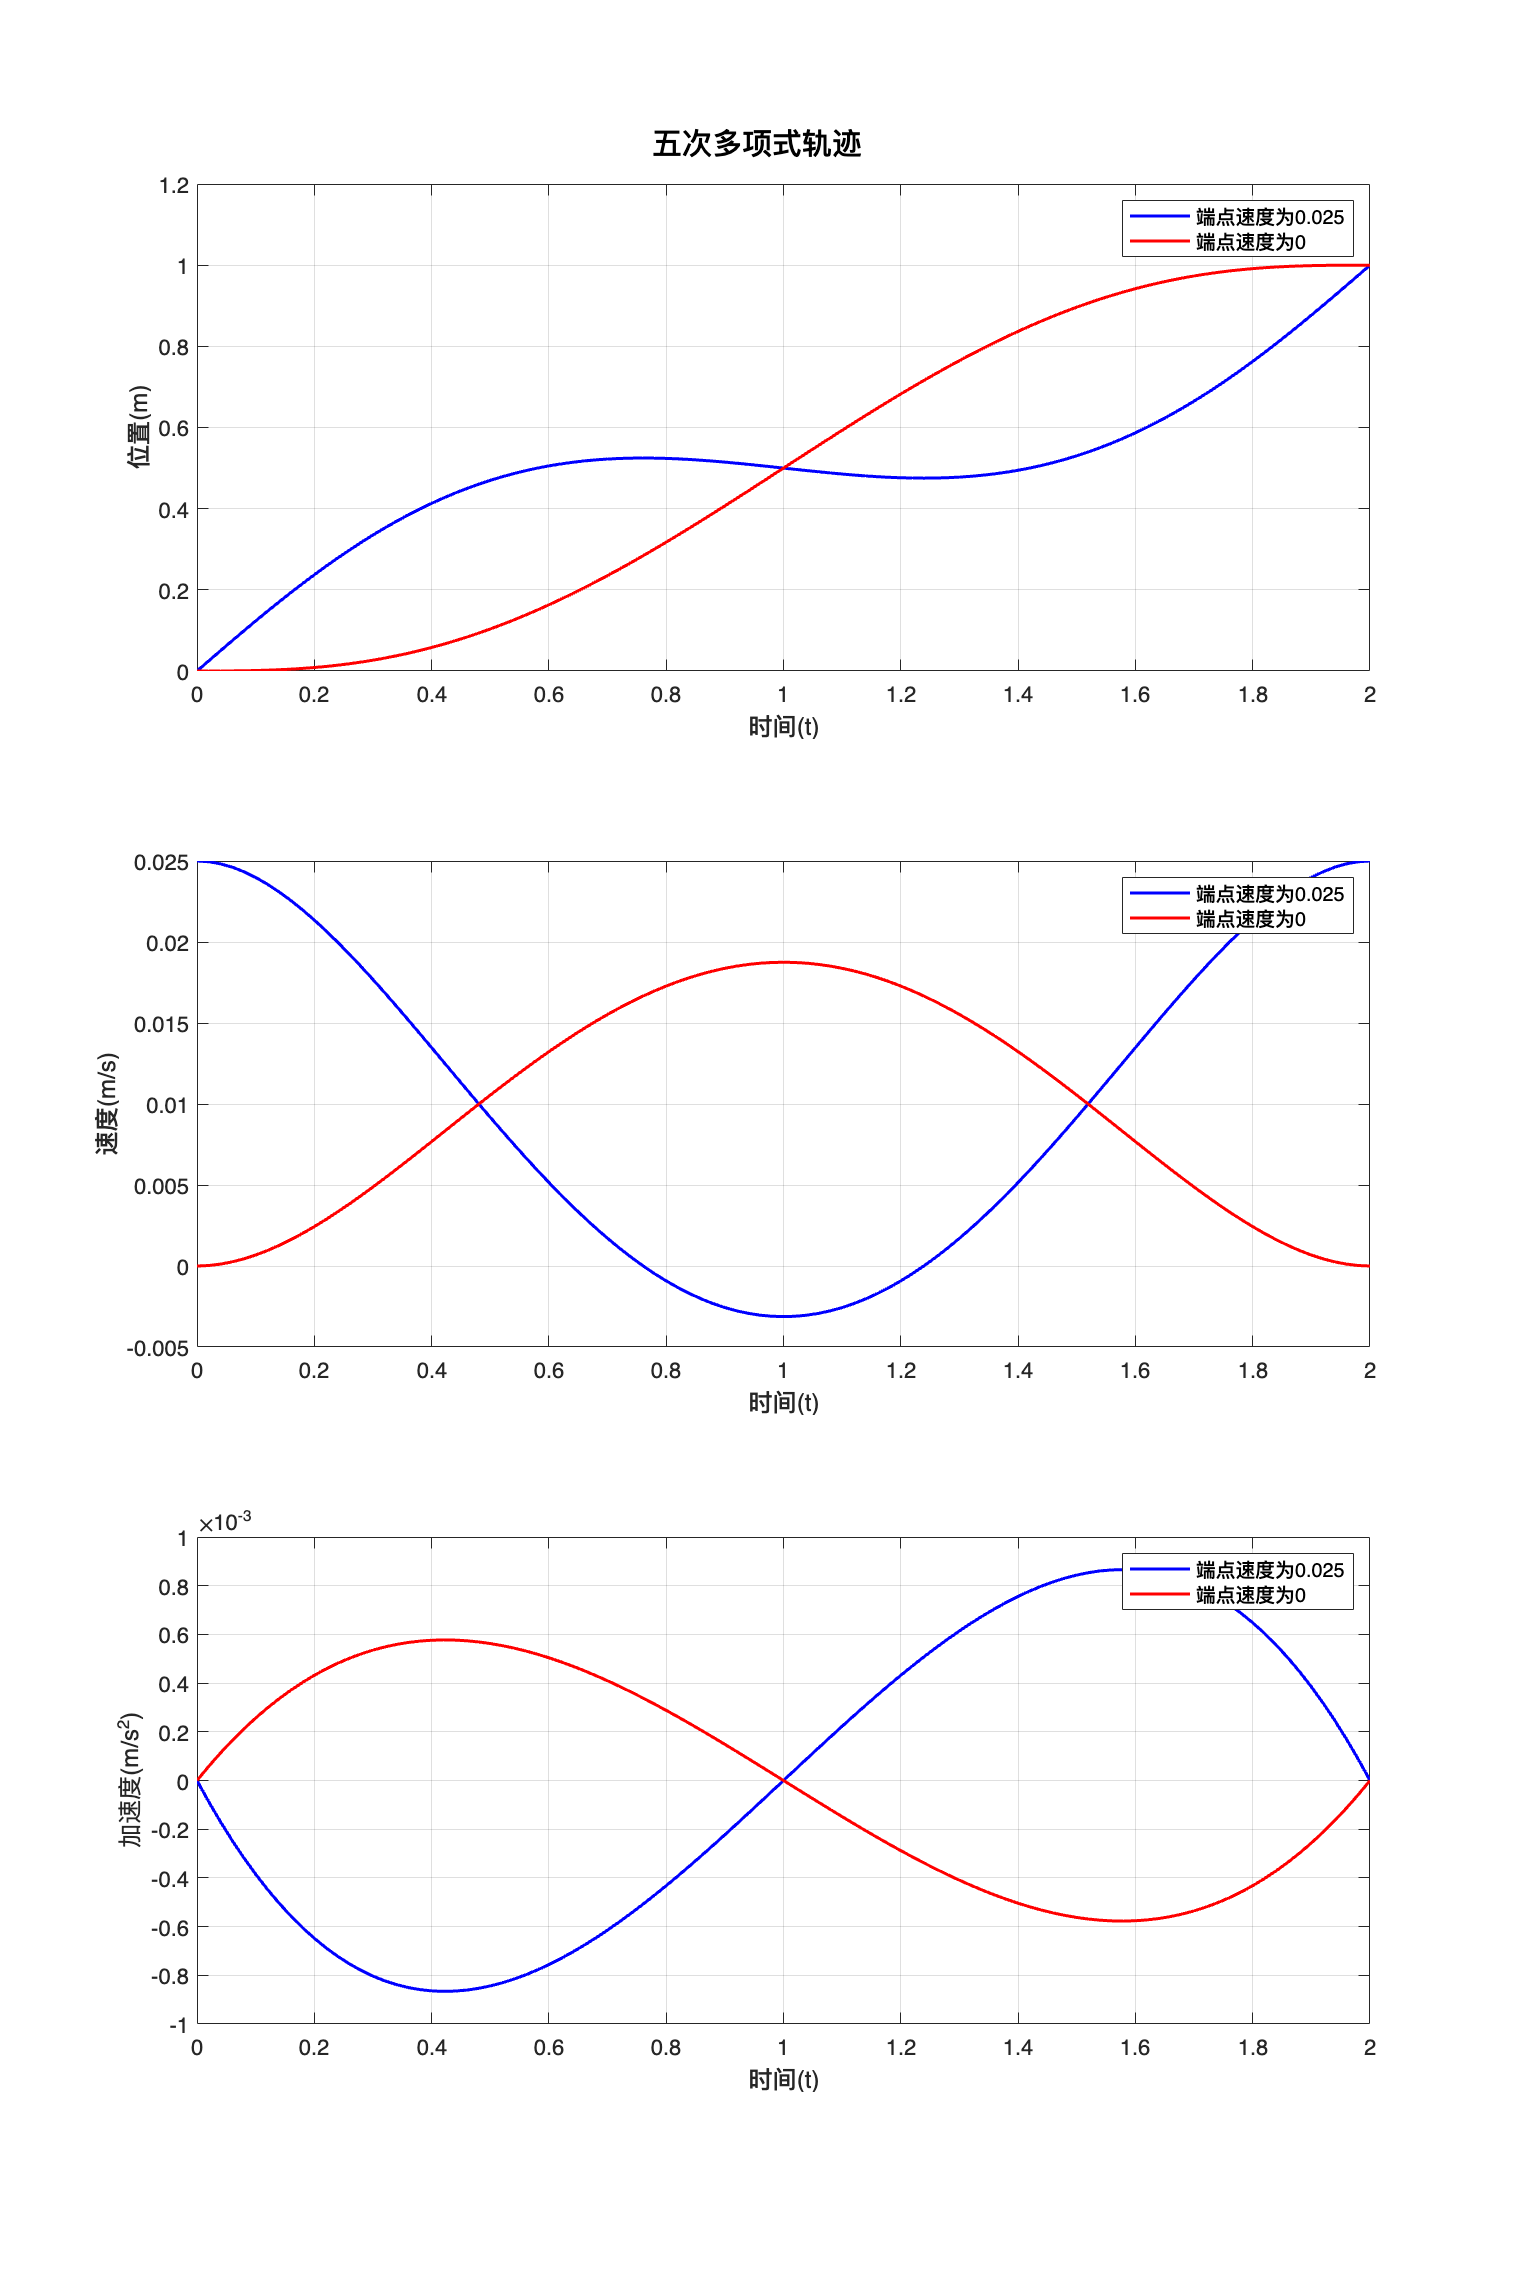

close all;
clear;
clc;

% 设置时间、插值步数
T = 2;
N = 100;
t = 0: T/N: T;  

% 端点速度为0.025
sd0 = 0.025;
sd1 = 0.025;
[s1,sd1,sdd1] = tpoly(0, 1, N+1, sd0, sd1);  % 指定起始点的速度

% 端点速度为0
[s,sd,sdd] = tpoly(0, 1, N+1);  

% 绘制曲线
figure('position',[0,0, 1200,1800]);
sgtitle('五次多项式轨迹') 

subplot(3,1,1); plot(t,s1,'b',t, s,'r','LineWidth', 1.5);  
xlabel('时间(t)'),ylabel('位置(m)'); grid;
legend('端点速度为0.025','端点速度为0');

subplot(3,1,2); plot(t,sd1,'b', t, sd,'r','LineWidth', 1.5); 
xlabel('时间(t)'),ylabel('速度(m/s)'); grid;
legend('端点速度为0.025','端点速度为0')

subplot(3,1,3); plot(t,sdd1,'b',t, sdd,'r','LineWidth', 1.5); 
xlabel('时间(t)'),ylabel('加速度(m/s^2)'); grid
legend('端点速度为0.025','端点速度为0')

# 3. 多维轨迹规划

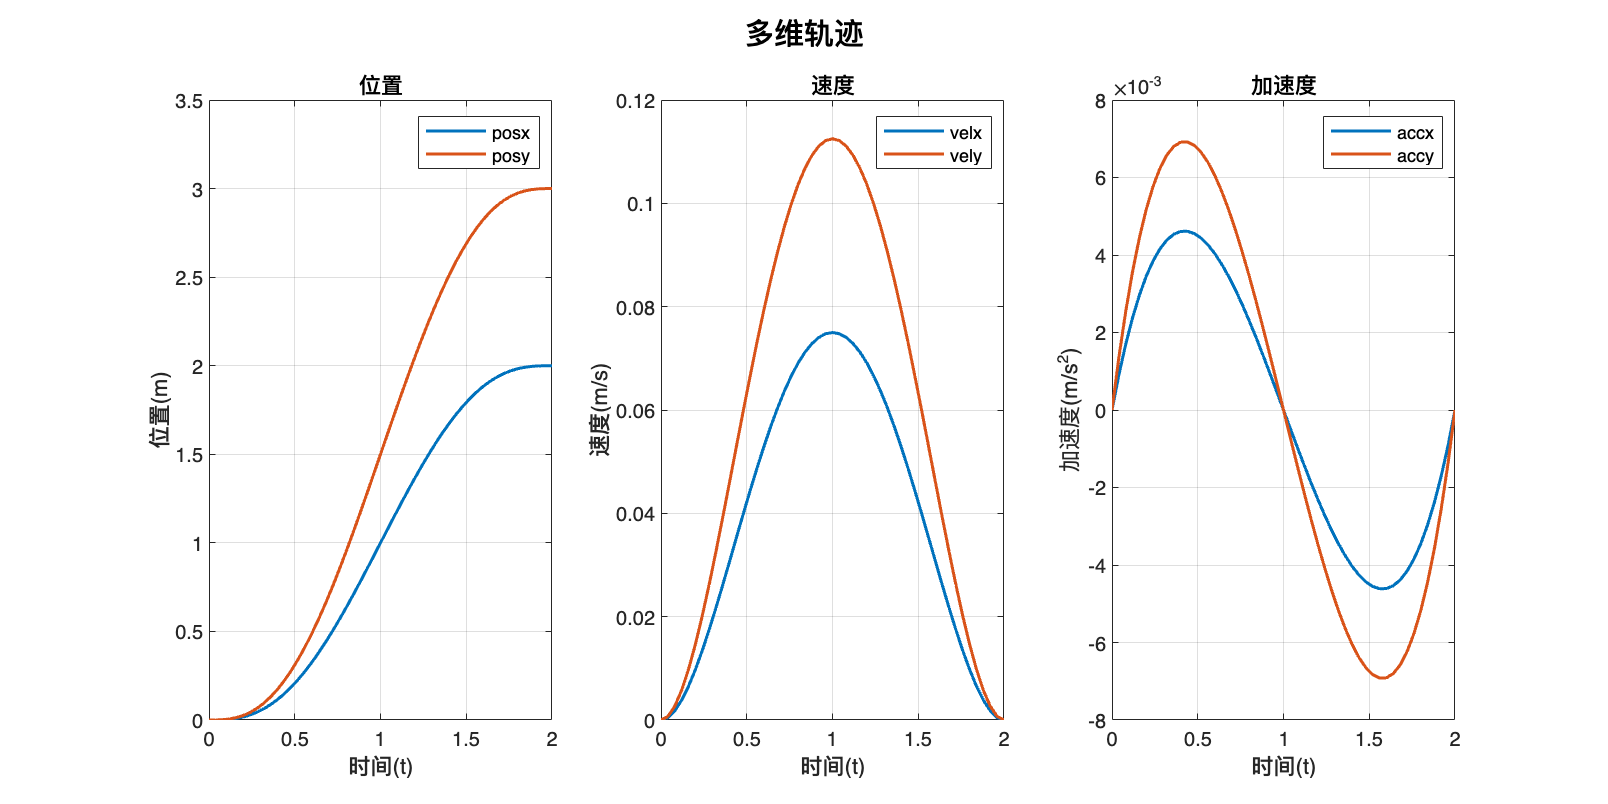

close all;
clear;
clc;

% 设置时间、插值步数
t = linspace(0,2,51); %// 时间 0:0.04:2

% %[Q,QD,QDD] = mtraj(TFUNC, Q0, QF, T)
% TFUNC：轨迹函数，可选@tpoly或@lspb
% Q0：初始位置
% QF：结束位置
% �T：时间序列
% x，y两维
[P,dP,ddP] = mtraj(@tpoly,[0,0],[2,3],t);

figure('position',[0,0, 1200,600]);
sgtitle('多维轨迹') 

subplot(1,3,1); 
plot(t,P, 'LineWidth', 1.5); 
title('位置');legend('posx','posy');
xlabel('时间(t)'),ylabel('位置(m)'); grid;

subplot(1,3,2); 
plot(t,dP,'LineWidth', 1.5);
title('速度');legend('velx','vely')
xlabel('时间(t)'),ylabel('速度(m/s)'); grid;

subplot(1,3,3); 
plot(t,ddP,'LineWidth', 1.5);
title("加速度");legend('accx','accy');
xlabel('时间(t)'),ylabel('加速度(m/s^2)'); grid

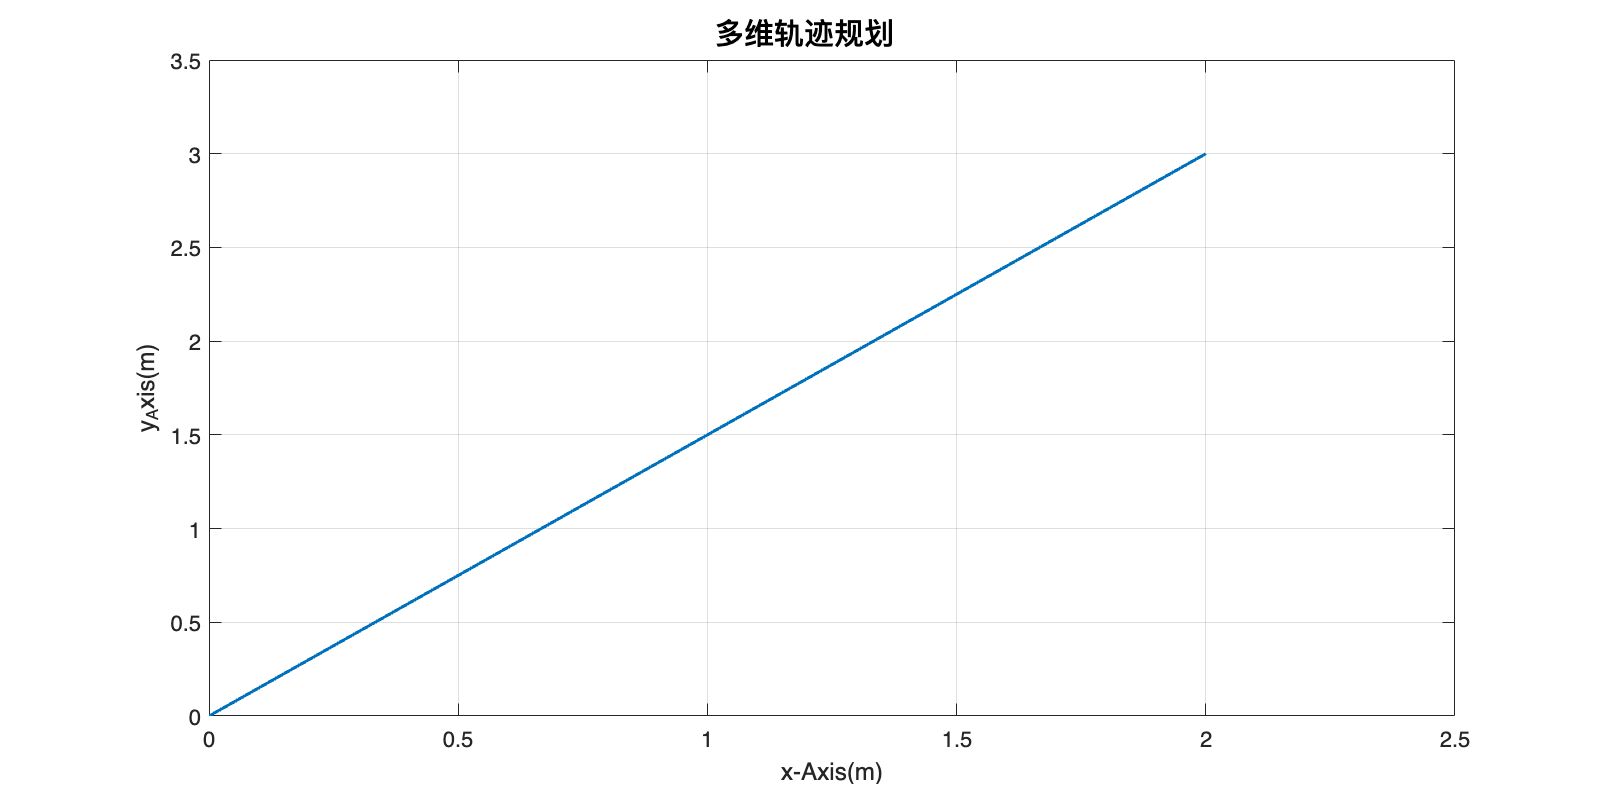



figure('position',[0,0, 1200,600]);
sgtitle('多维轨迹规划') 
plot(P(:,1),P(:,2), 'LineWidth', 1.5);
xlabel('x-Axis(m)'),ylabel('y_Axis(m)'); grid

# 4. 梯型轨迹（Matlab函数）

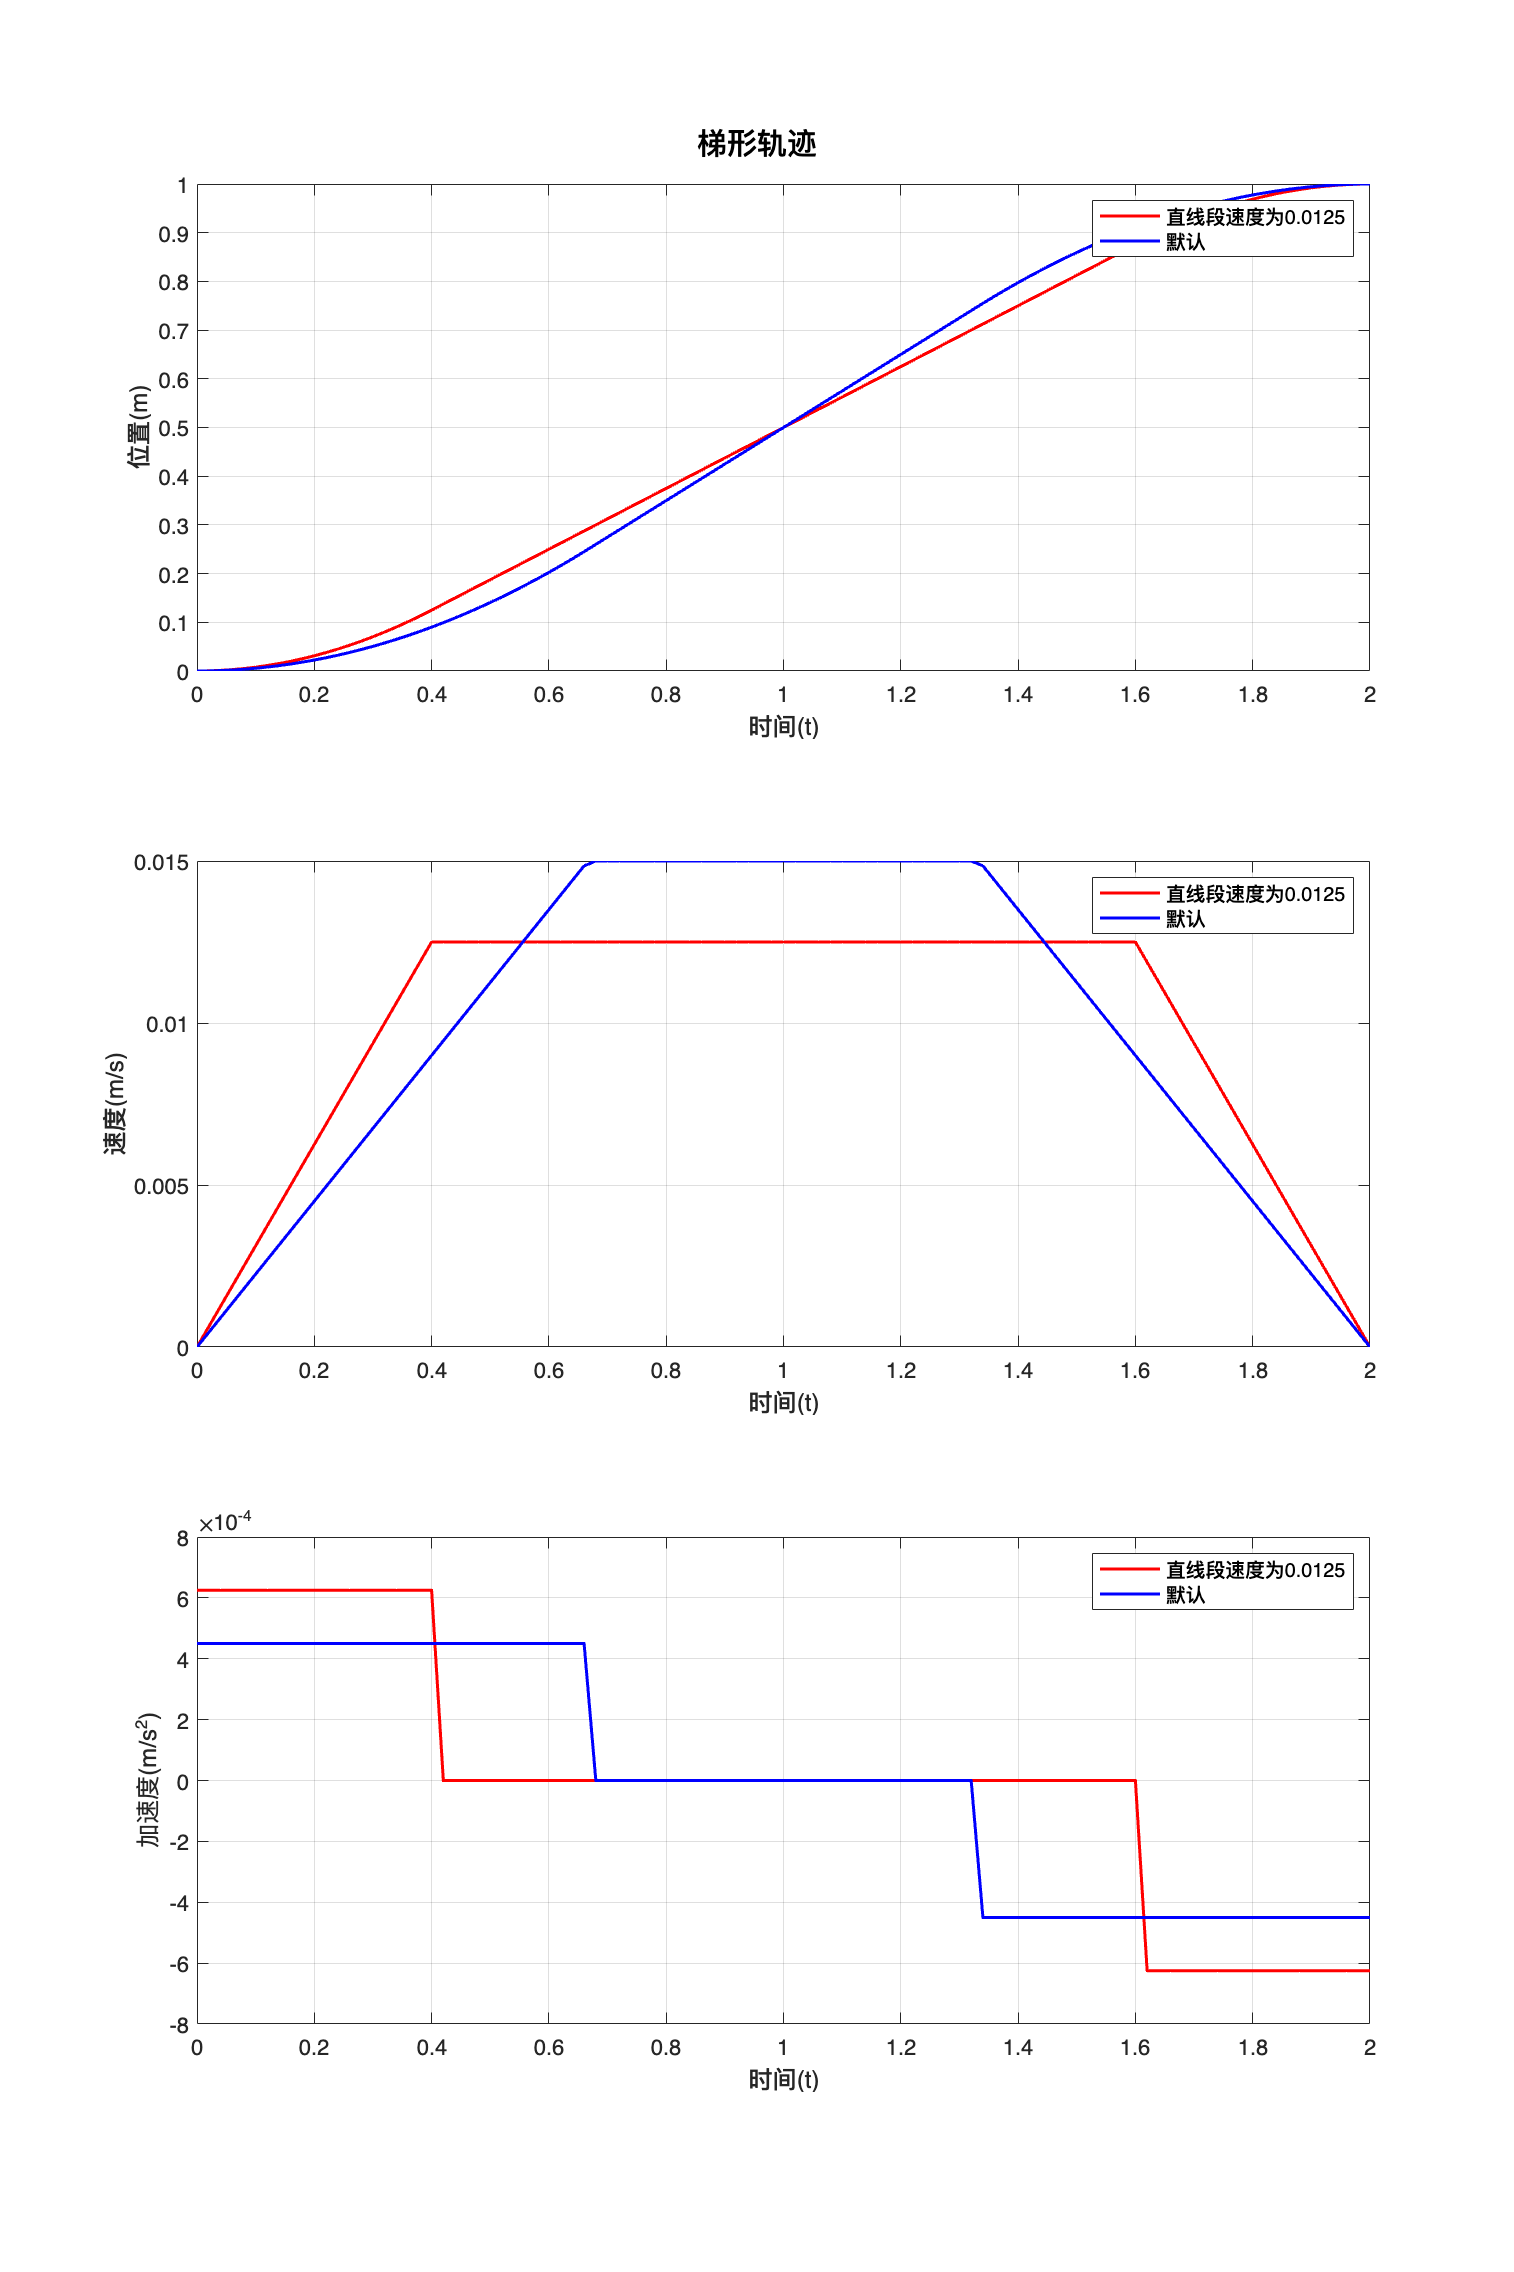

close all;
clear;
clc;

% 设置时间、插值步数
T = 2;
N = 100;
t = 0: T/N: T; 

% 调用lspb函数
Vmax = 0.0125;
[s1,sd1,sdd1] = lspb(0, 1, N+1, Vmax);   % 指定直线段速度
[s2,sd2,sdd2] = lspb(0, 1, N+1);         % 默认直线段速度

% 绘制曲线
figure('position',[0,0, 1200,1800]);
sgtitle('梯形轨迹') 

subplot(3,1,1); 
plot(t,s1,'r',t,s2,'b','LineWidth', 1.5); 
xlabel('时间(t)'),ylabel('位置(m)'); grid;
legend('直线段速度为0.0125','默认')

subplot(3,1,2); 
plot(t,sd1,'r',t,sd2,'b','LineWidth', 1.5); 
xlabel('时间(t)'),ylabel('速度(m/s)'); grid;
legend('直线段速度为0.0125','默认')

subplot(3,1,3);
plot(t,sdd1,'r',t,sdd2,'b','LineWidth', 1.5); 
xlabel('时间(t)'),ylabel('加速度(m/s^2)'); grid;
legend('直线段速度为0.0125','默认')

# 5. 多段多维轨迹

TRAJ = mstraj(WP, QDMAX, TSEG, QO, DT, TACC, OPTIONS)

� WP：路径点

� QDMAX：最大速度，和TSEG为同一个自由度，若设置了时间间隔，则最大速度置空。

� TSEG：每段的时间间隔，和QDMAX为同一个自由度，若设置了最大速度，则时间间隔置空。

� QO：初始位置，置为空时，WP第一个点必须为[0,0]

� DT：插值间隔

� TACC：加速时间

% 参数设置
wp = [0,0;  2,3;   1,2];
Dt = 0.04; 
TACC1 = 0.1;
TACC2 = 0.6;

% 计算轨迹
P1 = mstraj(wp,[],[1.5,1],[],Dt,TACC1);
P2 = mstraj(wp,[],[1.5,1],[],Dt,TACC2);
t = linspace(0,Dt*length(P1(:,1)),length(P1(:,1)));


% 绘制轨迹
figure('position',[0,0, 1200,800]) 
sgtitle('多段多维轨迹') 

subplot(1,2,1);
plot(t, P1, 'LineWidth', 1.5);
grid on;hold on; 
title('P1');
xlabel('时间(t)'),ylabel('位置(m)'); 
legend('posx','posy')

subplot(1,2,2);
plot(t, P2, 'LineWidth', 1.5);
grid on;hold on;
title('P2');
xlabel('时间(t)'),ylabel('位置(m)'); 
legend('posx','posy')

% 绘制路径
figure('position',[0,0, 1200,800]);
sgtitle('多维轨迹规划') 

subplot(1,2,1);
plot(P1(:,1),P1(:,2), 'LineWidth', 1.5);
xlabel('x-Axis(m)'),ylabel('y_Axis(m)'); 
axis equal; grid; hold on;
plot(wp(1,1),wp(1,2),'r*');
plot(wp(2,1),wp(2,2),'r*');
plot(wp(3,1),wp(3,2),'r*');


subplot(1,2,2);
plot(P2(:,1),P2(:,2), 'LineWidth', 1.5);
xlabel('x-Axis(m)'),ylabel('y_Axis(m)'); 
axis equal; grid; hold on;
plot(wp(1,1),wp(1,2),'r*');
plot(wp(2,1),wp(2,2),'r*');
plot(wp(3,1),wp(3,2),'r*');

# 6. S型轨迹

参考： https://blog.csdn.net/qq_26565435/article/details/94657852

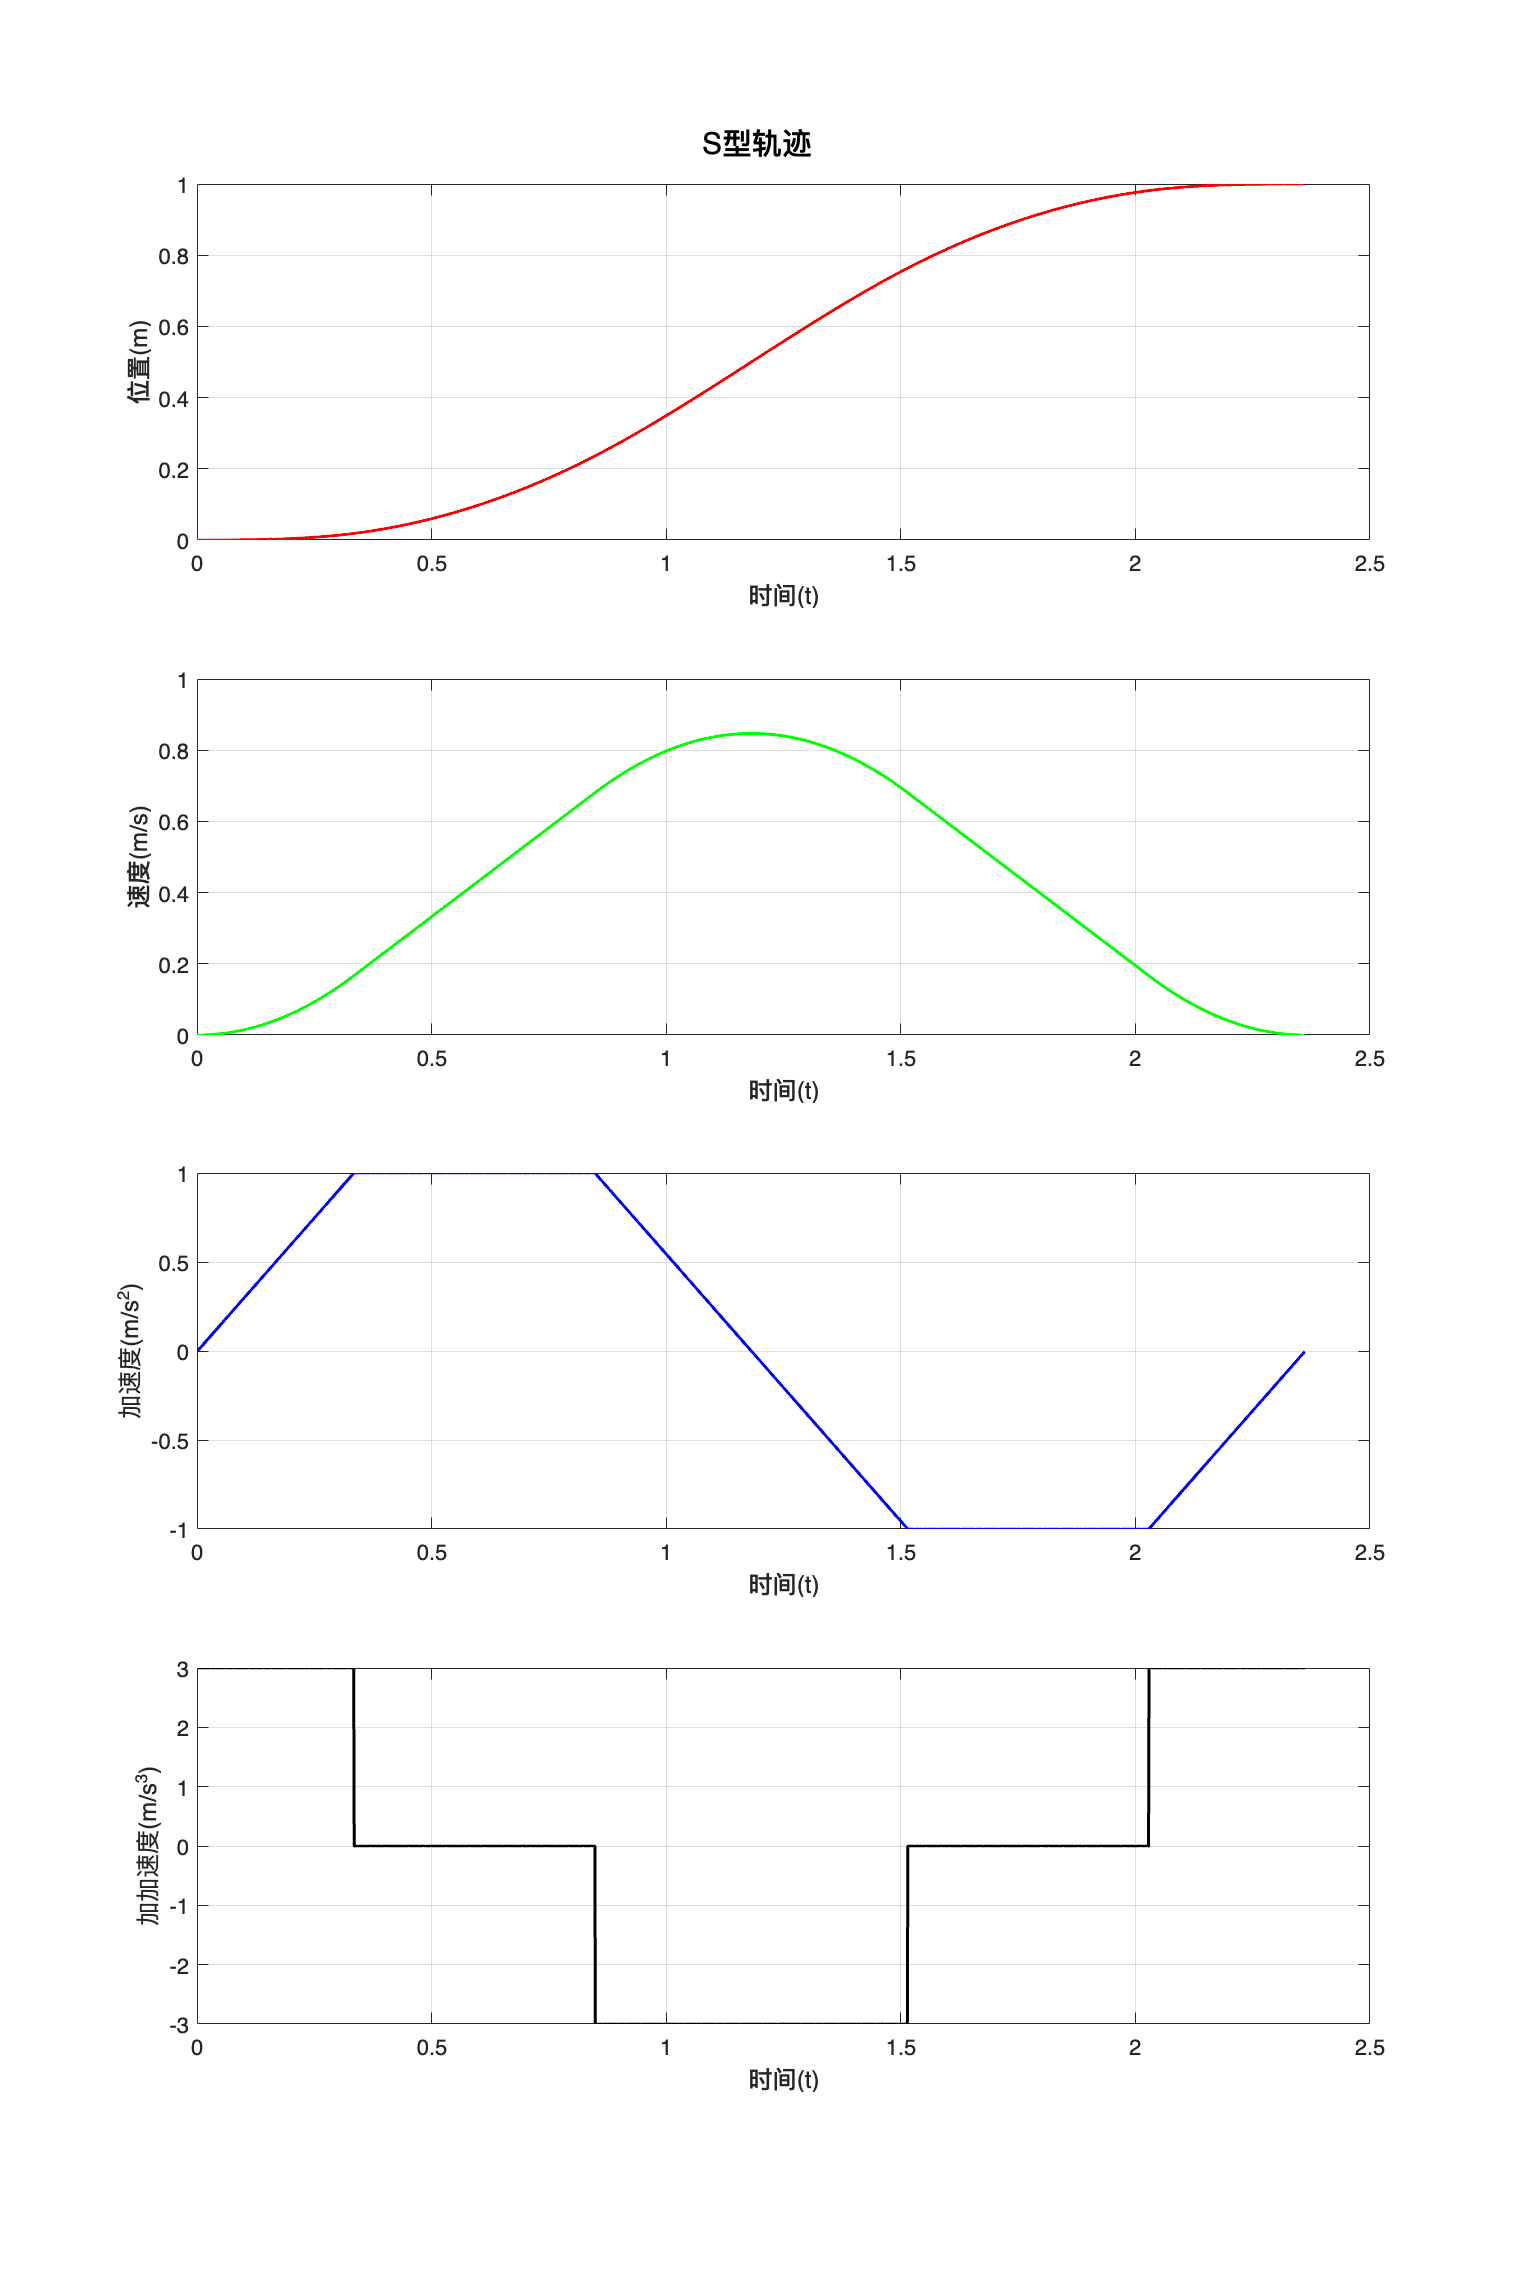

clear
clc
close all

% 边界条件
q0 = 0;  v0 = 0; 
q1 = 1;  v1 = 0;
vmax = 1; amax = 1; jmax = 3;

% 计算S曲线需要的参数
% 包括：Ta, Tv, Td, Tj1, Tj2, q0, q1, v0, v1, vlim, amax, amin, alima, alimd, jmax, jmin
para = STrajectoryPara(q0, q1, v0, v1, vmax, amax, jmax);
T = para(1) + para(2) + para(3);

% 计算曲线
i = 1; 
for t = 0: 0.001: T
   time(i) = 0.001*i;
   [w wd wdd wddd] = S_Trajectory(t, para);
   
   q(i) = w;
   qd(i) = wd;
   qdd(i) = wdd;
   qddd(i) = wddd;
   
   i = i + 1;
end

sigma = sign(q1 - q0);
q = sigma*q;
qd = sigma*qd;
qdd = sigma*qdd;
qddd = sigma*qddd;

% 绘图
figure('position',[0,0, 1200,1800]);
sgtitle('S型轨迹') 

subplot(4, 1, 1)
plot(time, q, 'r', 'LineWidth', 1.5);   
xlabel('时间(t)'),ylabel('位置(m)'); grid;

subplot(4, 1, 2)
plot(time, qd, 'g', 'LineWidth', 1.5);  
xlabel('时间(t)'),ylabel('速度(m/s)');  grid;

subplot(4, 1, 3)
plot(time, qdd, 'b', 'LineWidth', 1.5); 
xlabel('时间(t)'),ylabel('加速度(m/s^2)');  grid;

subplot(4, 1, 4)
plot(time, qddd, 'k', 'LineWidth', 1.5); 
xlabel('时间(t)'),ylabel('加加速度(m/s^3)');  grid;

function para = STrajectoryPara(q0, q1, v0, v1, vmax, amax, jmax)
% 得到规划参数Ta, Tv, Td, Tj1, Tj2, q0, q1, v0, v1, vlim, amax, amin, alima, alimd, jmax, jmin
% 用户给定参数
% 边界条件q0 = 10, q1 = 0, v0 = -7, v1 = 0
% 约束条件vmax = 10, amax = 10, jamx = 30
% q0 = 0; q1 = 10; 
% v0 = 7.5; v1 = 0;
% vmax = 10; amax = 10; jmax = 30;
vmin = -vmax; amin = -amax; jmin = -jmax;

%% 利用公式（3.31）（3.32）转化得到实际的q_0、q_1、v_max、a_max
sigma = sign(q1 - q0);  
q_0 = sigma*q0;
q_1 = sigma*q1;
v_0 = sigma*v0;
v_1 = sigma*v1;
v_max = ((sigma+1)/2)*vmax + ((sigma-1)/2)*vmin;
v_min = ((sigma+1)/2)*vmin + ((sigma-1)/2)*vmax;
a_max = ((sigma+1)/2)*amax + ((sigma-1)/2)*amin;
a_min = ((sigma+1)/2)*amin + ((sigma-1)/2)*amax;
j_max = ((sigma+1)/2)*jmax + ((sigma-1)/2)*jmin;
j_min = ((sigma+1)/2)*jmin + ((sigma-1)/2)*jmax;

%% 判断是否达到最大速度
if ((v_max - v_0)*j_max < a_max^2) 
    Tj1 = sqrt((v_max - v_0) / j_max); % 达不到a_max
    Ta = 2*Tj1;
    a_lima = j_max * Tj1;
else
    Tj1 = a_max / j_max; % 能够达到a_max
    Ta = Tj1 + (v_max - v_0) / a_max;
    a_lima = a_max;
end
if ((v_max - v_1)*j_max < a_max^2)
    Tj2 = sqrt((v_max - v_1) / j_max); % 达不到a_min
    Td = 2*Tj2;
    a_limd =  -j_max * Tj2;
else
    Tj2 = a_max / j_max; % 能够达到a_min
    Td = Tj2 + (v_max - v_1) / a_max;
    a_limd = -a_max;
end
% 根据（3.25）计算匀速段时间
Tv = (q_1 - q_0)/v_max - (Ta/2)*(1 + v_0/v_max) - (Td/2)*(1 + v_1/v_max);

%% 对Tv进行讨论
if (Tv > 0)
    % 达到最大速度v_max，即存在匀速阶段
    vlim = v_max;
    T = Ta + Tv + Td;
    para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
    return;
else
    % 达不到最大速度，即匀速阶段Tv=0
    % 假设最大加速度和最小加速度均能达到
    Tv = 0;
    Tj = a_max / j_max;
    Tj1 = Tj;
    Tj2 = Tj;
    delta = (a_max^4/j_max^2) + 2*(v_0^2 + v_1^2) + a_max*(4*(q_1 - q_0) - 2*(a_max/j_max)*(v_0 + v_1));
    Ta = ((power(a_max, 2)/j_max) - 2.0*v_0 + sqrt(delta)) / (2.0*a_max);
    Td = ((power(a_max, 2)/j_max) - 2.0*v_1 + sqrt(delta)) / (2.0*a_max);
    % 对Ta和Td进行讨论
    if (Ta < 0 || Td < 0)
        if (Ta < 0)
            % 没有加速段，只有减速段
            Ta = 0; Tj1 = 0;
            Td = 2*(q_1 - q_0) / (v_0 + v_1);
            Tj2 = (j_max*(q_1 - q_0) - sqrt(j_max*(j_max*power(q_1 - q_0, 2) + power(v_1 + v_0, 2)*(v_1 - v_0)))) / (j_max*(v_1 + v_0));
            a_lima = 0;
            a_limd = -j_max*Tj2;
            vlim = v0;
            para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
            return;
        elseif (Td < 0)
            % 没有减速段，只有加速段
            Td = 0; Tj2 = 0;
            Ta = 2*(q_1 - q_0) / (v_0 + v_1);
            Tj1 = (j_max*(q_1 - q_0) - sqrt(j_max*(j_max*power(q_1 - q_0, 2)) - power(v_1 + v_0, 2)*(v_1 - v_0))) / (j_max*(v_1 + v_0));
            a_lima = j_max*Tj1;
            a_limd = 0;
            vlim = v_0 + a_lima*(Ta - Tj1);
            para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
            return;
        end
    elseif (Ta >= 2*Tj && Td >= 2*Tj)
        % 加速段和减速段都能达到最大加速度
        a_lima = a_max;
        a_limd = -a_max;
        vlim = v0 + a_lima*(Ta - Tj);
        para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
        return;
    else
        % 加速和减速阶段至少有一段不能达到最大加速度
        lambda = 0.99; % 系统取0<lambda<1
        while (Ta < 2*Tj || Td < 2*Tj)
            % 循环
            a_max = lambda*a_max;
            Tv = 0;
            Tj = a_max / j_max;
            Tj1 = Tj;
            Tj2 = Tj;
            delta = (a_max^4/j_max^2) + 2*(v_0^2 + v_1^2) + a_max*(4*(q_1 - q_0) - 2*(a_max/j_max)*(v_0 + v_1));
            Ta = ((power(a_max, 2)/j_max) - 2.0*v_0 + sqrt(delta)) / (2.0*a_max);
            Td = ((power(a_max, 2)/j_max) - 2.0*v_1 + sqrt(delta)) / (2.0*a_max);
            if (Ta < 0 || Td < 0)
                if (Ta < 0)
                    % 没有加速段，只有减速段
                    Ta = 0; Tj1 = 0;
                    Td = 2*(q_1 - q_0) / (v_0 + v_1);
                    Tj2 = (j_max*(q_1 - q_0) - sqrt(j_max*(j_max*power(q_1 - q_0, 2) + power(v_1 + v_0, 2)*(v_1 - v_0)))) / (j_max*(v_1 + v_0));
                    a_lima = 0;
                    a_limd = -j_max*Tj2;
                    vlim = v0;
                    para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
                    return;
                elseif (Td < 0)
                    % 没有减速段，只有加速段
                    Td = 0; Tj2 = 0;
                    Ta = 2*(q_1 - q_0) / (v_0 + v_1);
                    Tj1 = (j_max*(q_1 - q_0) - sqrt(j_max*(j_max*power(q_1 - q_0, 2)) - power(v_1 + v_0, 2)*(v_1 - v_0))) / (j_max*(v_1 + v_0));
                    a_lima = j_max*Tj1;
                    a_limd = 0;
                    vlim = v_0 + a_lima*(Ta - Tj1);
                    para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
                    return;
                end
            elseif (Ta >= 2*Tj && Td >= 2*Tj)
                % 加速段和减速段都能达到最大加速度
                a_lima = a_max;
                a_limd = -a_max;
                vlim = v0 + a_lima*(Ta - Tj);
                para = [Ta, Tv, Td, Tj1, Tj2, q_0, q_1, v_0, v_1, vlim, a_max, a_min, a_lima, a_limd, j_max, j_min];
                return;
            end
        end
    end
end
end

% +++++++++++++++++++++++++++++++++++++++++++++++++++++++++
function [q qd qdd qddd] = S_Trajectory(t, par)

% 传递参数
Ta = par(1);     Tv = par(2);    Td = par(3);   
Tj1 = par(4);    Tj2 = par(5);   
q0 = par(6);     q1 = par(7) ;     
v0 = par(8);     v1 = par(9);   vlim = par(10);  
amax = par(11);  amin = par(12);
alima = par(13); alimd = par(14); 
jmax = par(15);  jmin = par(16);
T = Ta + Tv + Td;

%% 计算位移
% 加速段
if (t >= 0 && t < Tj1)
    q = q0 + v0*t + jmax*t^3/6;
    qd = v0 + jmax*(t^2/2);
    qdd = jmax*t;
    qddd = jmax;
elseif (t >= Tj1 && t < Ta - Tj1)
    q = q0 + v0*t +(alima/6)*(3*t^2 - 3*Tj1*t + Tj1^2);
    qd = v0 + alima*(t - Tj1/2);
    qdd = alima;
    qddd = 0;
elseif (t >= Ta - Tj1 && t < Ta)
    q = q0 + (vlim + v0)*(Ta/2) - vlim*(Ta - t) - jmin*((Ta - t)^3/6);
    qd = vlim + jmin*(power(Ta - t, 2)/2);
    qdd = -jmin*(Ta - t);
    qddd = jmin;
% 匀速段
elseif (t >= Ta && t < Ta + Tv)
    q = q0 + (vlim + v0)*(Ta/2) + vlim*(t - Ta);
    qd = vlim;
    qdd = 0;
    qddd = 0;
% 减速段
elseif (t >= Ta + Tv && t < T - Td + Tj2)
    q = q1 - (vlim + v1)*(Td/2) + vlim*(t - T + Td) - jmax*(power(t - T + Td, 3)/6);
    qd = vlim - jmax*(power(t - T + Td, 2)/2);
    qdd = -jmax*(t - T + Td);
    qddd = -jmax;
elseif (t >= T - Td + Tj2 && t < T - Tj2)
    q = q1 - (vlim + v1)*(Td/2) + vlim*(t - T + Td) + (alimd/6)*(3*power(t - T + Td, 2) - 3*Tj2*(t - T + Td) + Tj2^2);
    qd = vlim + alimd*(t - T + Td - Tj2/2);
    qdd = alimd;
    qddd = 0;
elseif (t >= T - Tj2 && t <= T)
    q = q1 - v1*(T - t) - jmax*(power(T - t, 3)/6);
    qd = v1 + jmax*(power(t - T, 2)/2);
    qdd = -jmax*(T - t);
    qddd = jmax;
end
end
% 按照S曲线的定义就可以确定这段程序
